x = linspace(0,2*pi);
y = linspace(0,2*pi);
[X,Y] = meshgrid(x,y);
Z = cos(X)+cos(Y)

Z =     2.0000    1.9980    1.9920    1.9819    1.9679    1.9501    1.9284    1.9029    1.8738    1.8413    1.8053    1.7660    1.7237    1.6785    1.6306    1.5801    1.5272    1.4723    1.4154    1.3569    1.2969    1.2358    1.1736    1.1108    1.0476    0.9841    0.9208    0.8577    0.7952    0.7335    0.6729    0.6137    0.5559    0.5000    0.4461    0.3944    0.3451    0.2985    0.2547    0.2139    0.1763    0.1420    0.1112    0.0839    0.0603    0.0405    0.0246    0.0126    0.0045    0.0005
    1.9980    1.9960    1.9899    1.9799    1.9659    1.9481    1.9264    1.9009    1.8718    1.8392    1.8033    1.7640    1.7217    1.6765    1.6285    1.5780    1.5252    1.4703    1.4134    1.3549    1.2949    1.2337    1.1716    1.1088    1.0456    0.9821    0.9187    0.8557    0.7932    0.7315    0.6709    0.6116    0.5539    0.4980    0.4441    0.3924    0.3431    0.2965    0.2527    0.2119    0.1743    0.1400    0.1092    0.0819    0.0583    0.0385    0.0226    0.0105    0.0025   -0

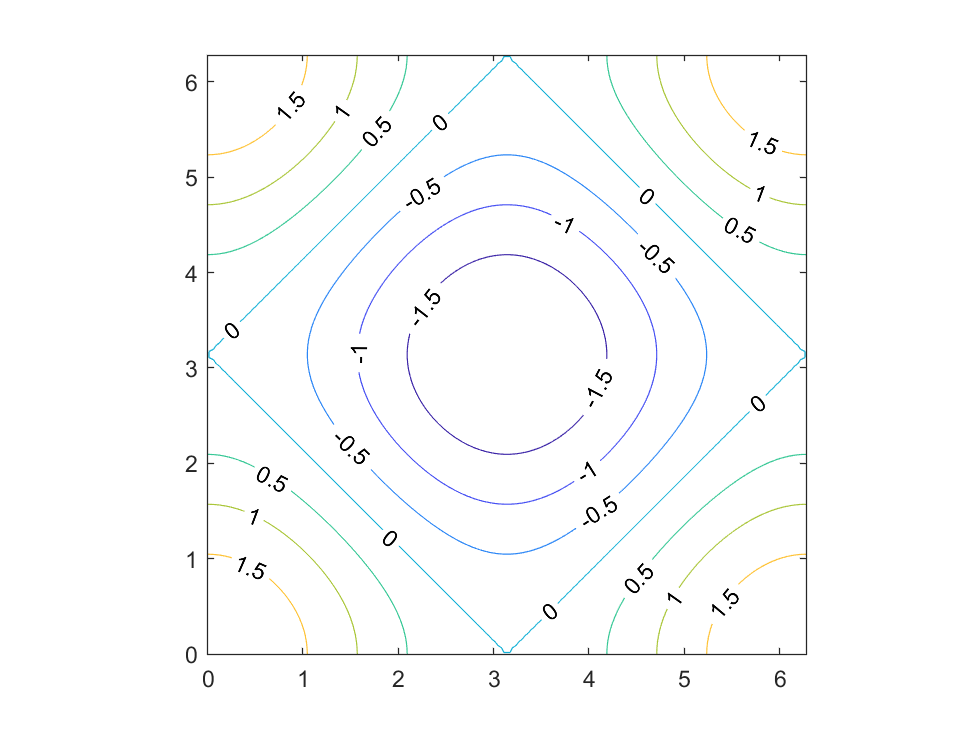

contour(X,Y,Z,'ShowText',"on")
axis equal

planes = planeData(2:end,:);
Fpatterson = F(2:end);

points = 50;

position = ones([1 points]).*linspace(0,1,points);
P = zeros([points points points]);

for u = 1:points
    for v = 1:points
        for w = 1:points
            for plane = 1:length(planes)
                h = planes(plane,1);
                k = planes(plane,2);
                l = planes(plane,3);
                
                P(u,v,w) = ...
                    ((abs(Fpatterson(plane)))^2)*...
                    exp(-1i*2*pi*(h*position(u)+k*position(v)+l*position(w)));
            end
        end
    end
end

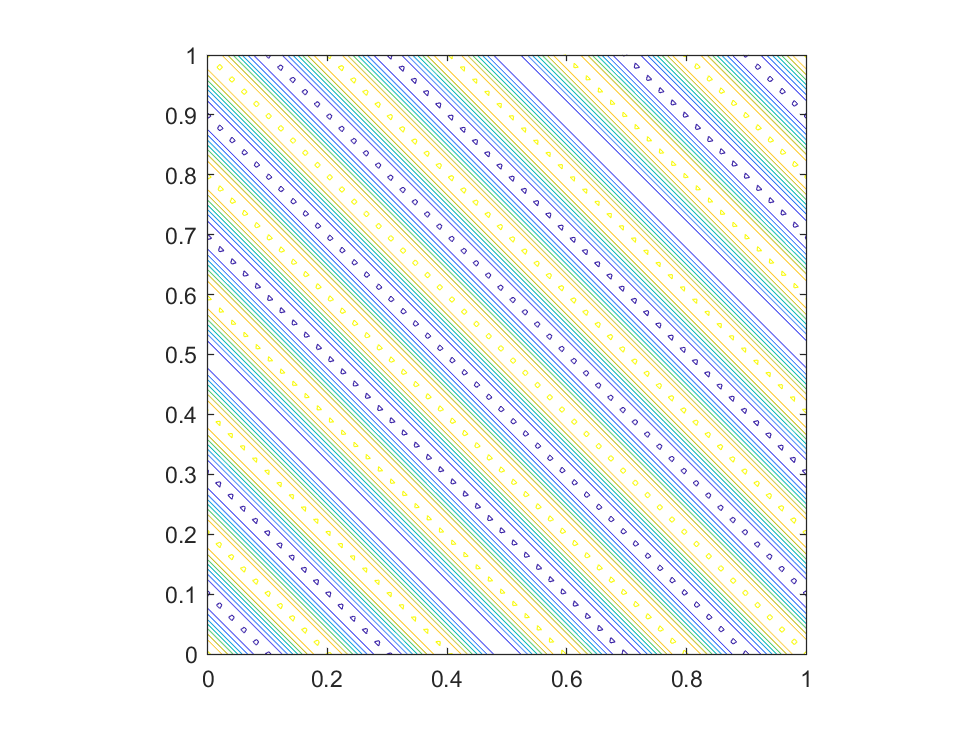

contour(position,position,real(P(:,:,1)))
axis equal